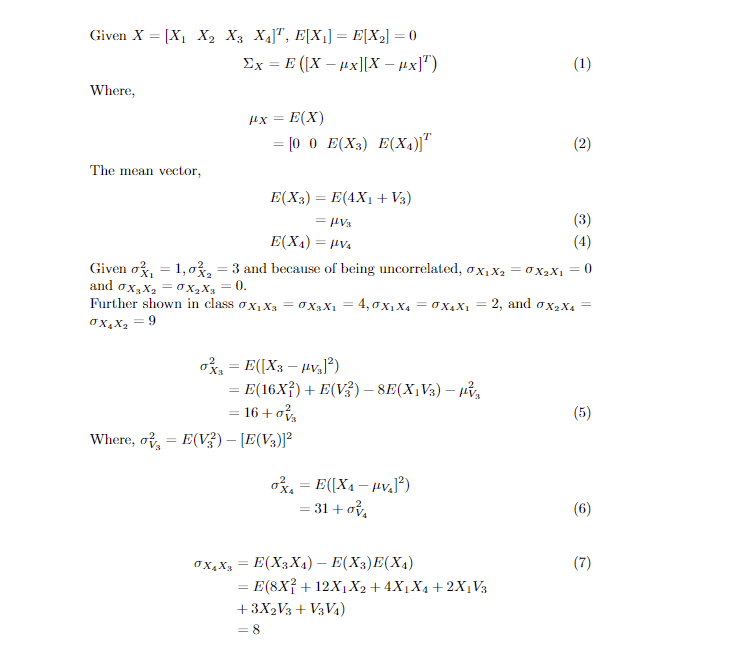

%% Data generation
rng(1)
N = 1000;
x1 = normrnd(0,sqrt(1),N,1);
x2 = normrnd(0,sqrt(3),N,1);
v3 = normrnd(0,1,N,1);
v4 = normrnd(0,1,N,1);
x3 = 4*x1 + v3;
x4 = 2*x1 + 3*x2 + v4;
% Data matrix
X = [x1 x2 x3 x4];

#### Covariance and Partial (Normalised Inverse) Correlation computation

% Covariance
covX = cov(X)
% Correlation
corrX = corr(X)
% Inverse correlation
icorrX  = inv(corrX);
% Scaling matrix for PC calculation
scal_mat = diag(1./sqrt(diag(icorrX)));
% Partial or conditional correlation (alternatively use parcorr routine)
pcorrX = -scal_mat*icorrX*scal_mat